### Setup

clear variables 
% Sound driver parameters
Buffersize = 1024;
RecorderChannelMapping = [1 2 3 4 5 6];

% Struct for often used constants
Constants = struct( ...
    'Samplerate', 48000, ...
    'AmountOfMicrophones', length(RecorderChannelMapping), ...
    'UCARadius', 0.40 / 2, ...
    'SpeedOfSound', 343, ...
    'SoundOutputOffset', 0.116 / 2, ... % From Genelec 8010A datasheet (half depth)
    'AlphaOffset', 30, ... % Offset betweeen x-axis and mic 1 in degrees
    'AmountOfTaus', 301, ...
    'AmountOfPhis', 360, ...
    'AmountOfOmegas', 600 ...
    );

% Distance parameters
OffsetMin = (2518 - 0.15 / Constants.SpeedOfSound * Constants.Samplerate) / Constants.Samplerate * Constants.SpeedOfSound;
OffsetMax = (2534 - 0.25 / Constants.SpeedOfSound * Constants.Samplerate) / Constants.Samplerate * Constants.SpeedOfSound;
MinDistance = 0.5;
MaxDistance = 2.0;

% Execution paths
LiveRecording =false;
Synthesized = true;

Debugging = false;
Continuously = false;

### Loading sound

% Define the sound we want to play
if Synthesized
    load("synthesized_signals.mat")
    ProbeSound = signals.clean;
    Constants.SignalLength = length(ProbeSound);
    Constants.AmountOfMicrophones = 3;
    Constants.AlphaOffset = 60;
    Constants.Samplerate = 24000;
else
    t = 0:1/Constants.Samplerate:0.5;
    ProbeSound = transpose(chirp(t, 50, t(end), 1000, "linear"));
    
    % Since the sound we wish to play is larger than than buffersize. We need to
    % partition the sound that is going to be played, such that it fits with the
    % buffersize. We choose to pad the sound with silence, such that it fits
    ElementsToAdd = (Buffersize - mod(length(ProbeSound), Buffersize));
    ProbeSound = padarray(ProbeSound, ElementsToAdd, 'post');
    
    % Adding silent frames to the end of the probe sound and scaling it
    SilentFramesToAdd = 24;
    Amplitude = 1;
    ProbeSound = padarray(ProbeSound, Buffersize*SilentFramesToAdd, 'post');
    ProbeSound = ProbeSound * Amplitude;
    
    Constants.SignalLength = length(ProbeSound);
    
    % Reshape the sounds to fit with the buffersize
    SoundPartitions = reshape(ProbeSound, Buffersize, []);
end

### Precalculations

PreCalcStart = tic;
% Calculate angular position of microphones
Constants.Betas = UCAangles(Constants.AmountOfMicrophones, Constants.AlphaOffset);

% Define linspaces for Phis, Taus, Omegas
Phis = linspace(0, deg2rad(359), Constants.AmountOfPhis); % In rad
Taus = linspace(MinDistance, MaxDistance, Constants.AmountOfTaus) * 2 / Constants.SpeedOfSound * Constants.Samplerate; % In samples
Omegas = round(linspace(1, Constants.Samplerate, Constants.AmountOfOmegas)); % In Hz
OmegasAngular = Omegas * 2 * pi; % In rad/sample
OmegasAngular(Constants.AmountOfOmegas/2:end) = OmegasAngular(Constants.AmountOfOmegas/2:end) - Constants.Samplerate * 2 * pi

OmegasAngular = 	1.0e+04 *

    0.0006    0.0258    0.0509    0.0760    0.1012    0.1263    0.1514    0.1766    0.2023    0.2275    0.2526    0.2777    0.3028    0.3280    0.3531    0.3782    0.4034    0.4285    0.4536    0.4788    0.5039    0.5290    0.5542    0.5793    0.6051    0.6302    0.6553    0.6805    0.7056    0.7307    0.7559    0.7810    0.8061    0.8313    0.8564    0.8815    0.9067    0.9318    0.9569    0.9827    1.0078    1.0330    1.0581    1.0832    1.1084    1.1335    1.1586    1.1838    1.2089    1.2340


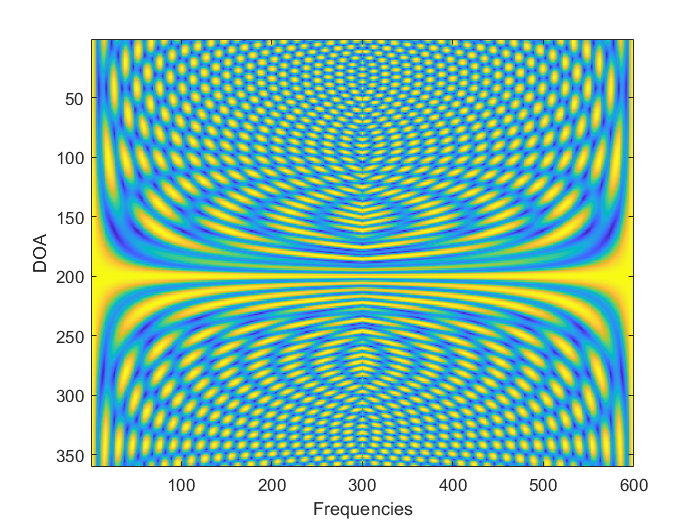

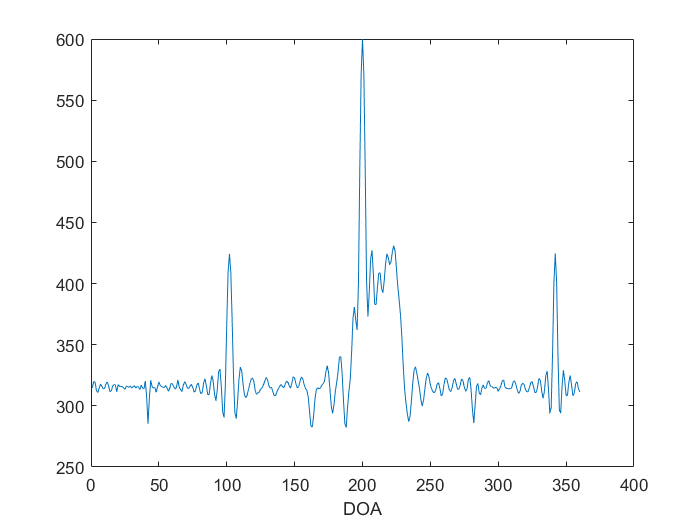

%OmegasAngular(Constants.AmountOfOmegas/2:end) = flip(OmegasAngular(Constants.AmountOfOmegas/2:end)) - Constants.Samplerate * pi

% Find the one sided FFT of the received sound
%nFFT = 2^nextpow2(length(ProbeSound));
nFFT = Constants.AmountOfOmegas;
ProbeFFT = TwoSidedFFT(ProbeSound, "nFFT", nFFT);
    %"Plot", true, "Samplerate", Constants.Samplerate);

% Define linspaces for indexing Omegas
OmegasBinIndices = linspace(0, Constants.AmountOfOmegas-1, Constants.AmountOfOmegas);
OmegasFFTIndices = ceil(Omegas * nFFT / Constants.Samplerate);

% Find the beamformer weights
SteeringVectors = SteeringVector(Phis, OmegasAngular, Constants);
[wDS, wDSHermitian] = BeamformerDS(SteeringVectors, Constants, ...
    "Plot", true, "LookingDirection", 200);


% Calculate Zbar
Zbar = CalculateZbar(ProbeFFT(OmegasFFTIndices), Phis, Taus, OmegasBinIndices, Constants);

toc(PreCalcStart)

Elapsed time is 9.956641 seconds.


%clear OmegasBinIndices ProbeFFT 

### Sound driver

if LiveRecording
    SoundDriver = audioPlayerRecorder( ...
        "SampleRate", Constants.Samplerate, ...
        "Device", "ZOOM Audio IF with Rec ASIO", ... % You must choose your own device
        'SupportVariableSize', true, ...
        "BufferSize", Buffersize, ...
        "RecorderChannelMapping", RecorderChannelMapping, ...
        "BitDepth", '32-bit float' ...  
        );
    
    if Debugging
        InputScope = timescope( ...
            'Name', 'Input', ...
            'SampleRate', Constants.Samplerate, ...
            'BufferLength', Buffersize, ...
            'AxesScaling', "auto", ...
            'TimeSpanSource', "property", ... 
            'TimeSpan', 5 ...
            );
        
        OutputScope = timescope( ...
            'Name', 'Output', ...
            'SampleRate', Constants.Samplerate, ...
            'BufferLength', Buffersize, ...
            'AxesScaling', "auto", ...
            'TimeSpanSource', "property", ... 
            'TimeSpan', 5 ...
            );
        
        InputScope.show;
        OutputScope.show;
    end
end

### Echolocation

while true
    EchoStart = tic;
    if Synthesized
        ReceivedSound = signals.reflec;
    elseif LiveRecording
        % Play the sound and store the recorded data into ReceivedSound
        ReceivedSound = PlayAndRecordSound(SoundDriver, SoundPartitions, Constants.AmountOfMicrophones);
        %ReceivedSound = RemoveDelay(ReceivedSound, Constants);
    else
        ReceivedSound = struct2array(load('Recordings\1.2Meter30Degree.mat'));
        %ReceivedSound = RemoveDelay(ReceivedSound, Constants);
    end
    
    % Find the one sided FFT of the received sound
    ReceivedFFT = transpose(TwoSidedFFT(ReceivedSound, "nFFT", nFFT));
    
    %Plots for debugging
    for i = 1: Constants.AmountOfMicrophones
        figure
        plot(ReceivedSound(:, i))
        title("Mic" + i + ": Time domain")
        figure
        plot(abs(ReceivedFFT(i, :)))
        title("Mic" + i + ": Frequency domain, All frequencies")
        figure
        plot(abs(ReceivedFFT(i, OmegasFFTIndices)))
        title("Mic" + i + ": Frequency domain, Specified frequencies")
    end
    
    % Calculate Ybar
    Ybar = CalculateYbar(ReceivedFFT, OmegasFFTIndices, wDSHermitian, Constants, ...
       "Plot", true);
    figure
    plot(abs(Ybar(1, :)))
    
    % Find the cost matrix
    CostMatrix = CostFunction(Ybar, Zbar, Constants, ...
        "Plot", true);
    
    % Determine the angle and distance from the cost matrix
    [Angle, Distance] = Estimator(Phis, Taus, CostMatrix, Constants)

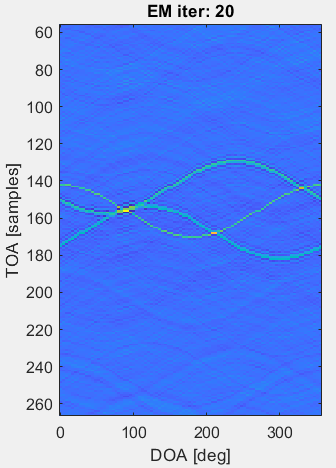 Distance: 1.11, DOA: 90

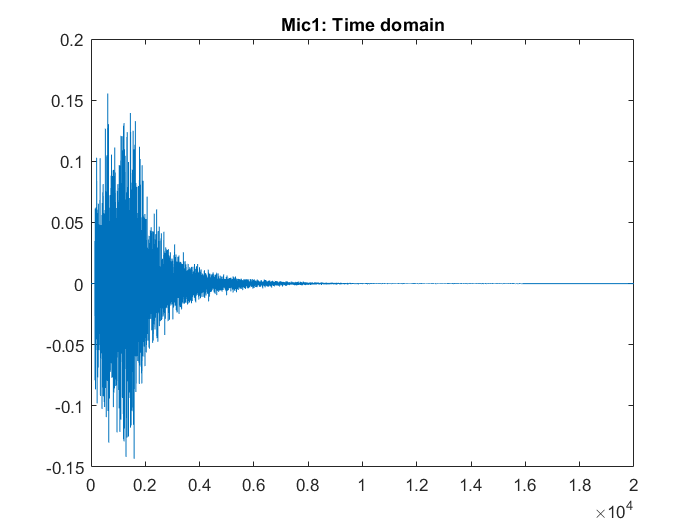

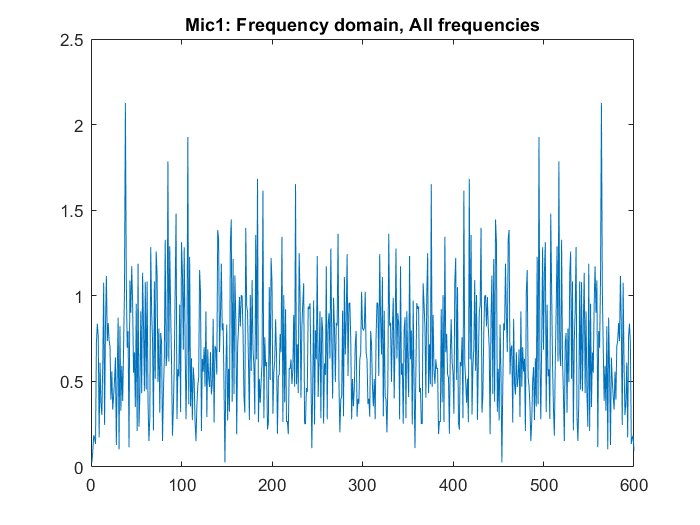

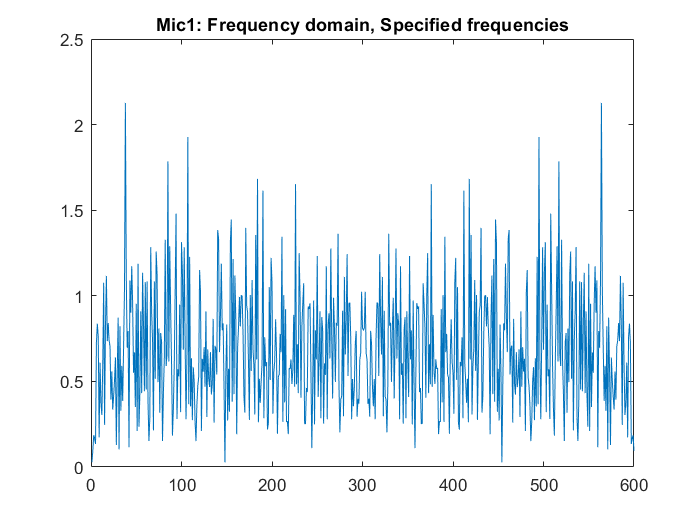

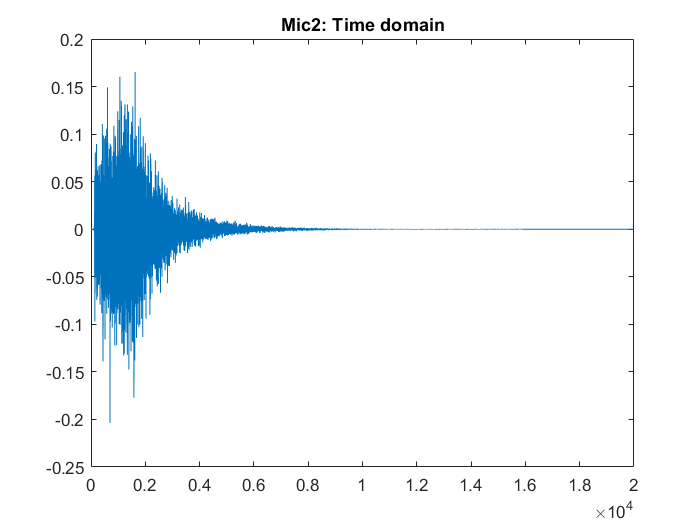

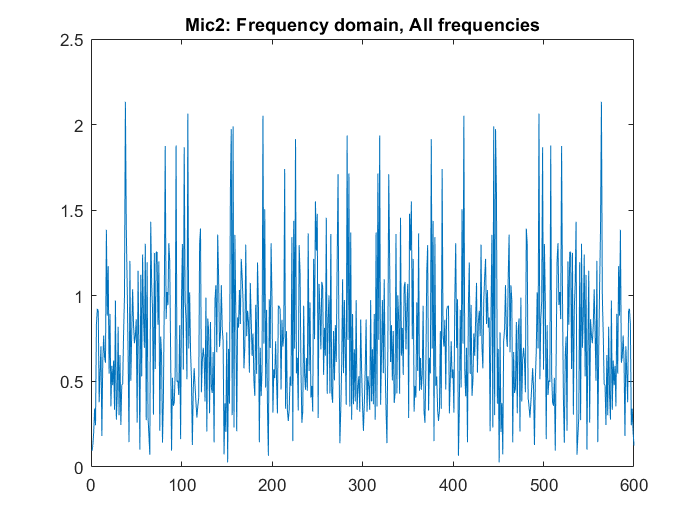

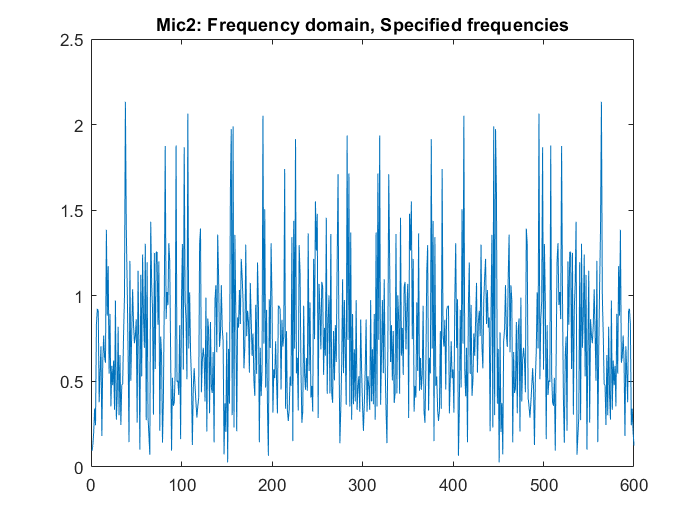

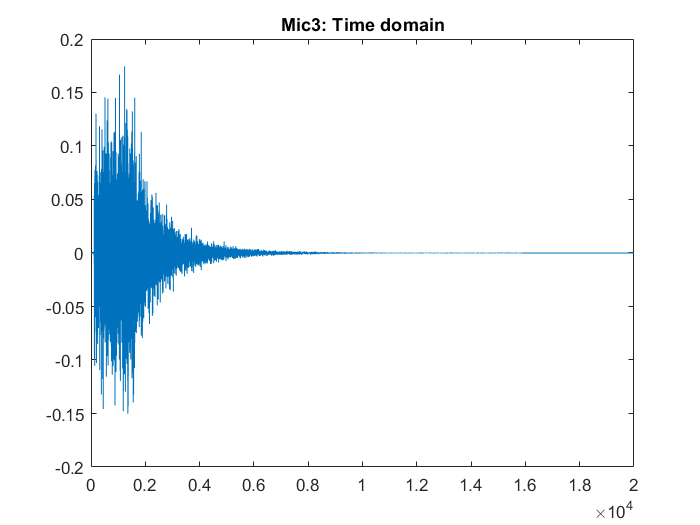

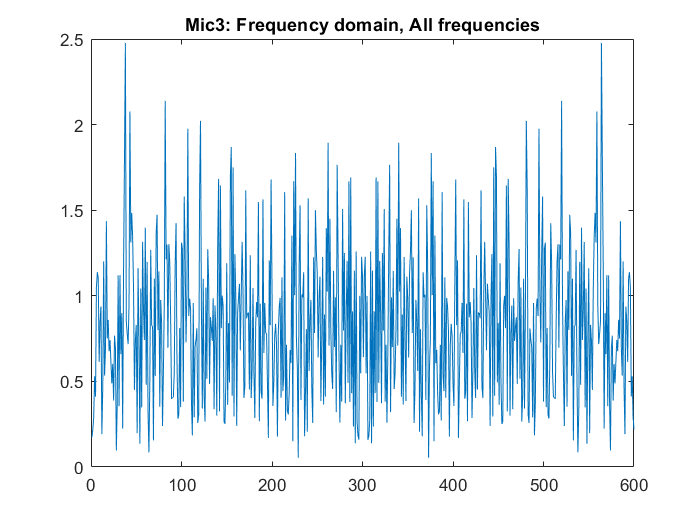

Angle = 271

Distance = 0.9200

Elapsed time is 2.765232 seconds.


    
    toc(EchoStart)
    
    if ~Continuously
        break;
    end
end

SaveSound = ReceivedSound;